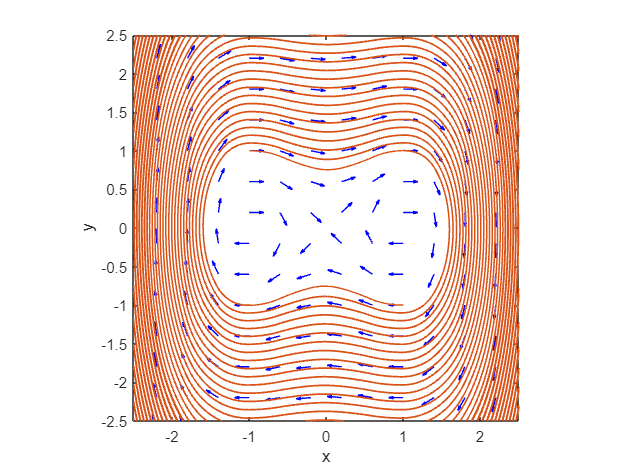

% Define the system as a function handle
f = @(t, u) [u(2); -u(1)^3 + u(1)];

% Define the grid for phase portrait
[x, y] = meshgrid(linspace(-5, 5, 26), linspace(-5, 5, 26));

dx = y;
dy = -x.^3 + x;

% Normalize arrows for consistent size
magnitude = sqrt(dx.^2 + dy.^2);
dx = dx ./ magnitude;
dy = dy ./ magnitude;

% Plot the direction field using quiver
figure;
quiver(x, y, dx, dy, 0.35, 'b'); hold on;

% Add streamlines to show phase portrait
startx = linspace(-3, 3, 4);
starty = linspace(-3, 3, 4);
[STARTX, STARTY] = meshgrid(startx, starty);
streamline(x, y, dx, dy, STARTX, STARTY);

% Axis and labels
axis tight;
axis equal; axis([-2.5 2.5 -2.5 2.5]);
xlabel('x');
ylabel('y');
title('');